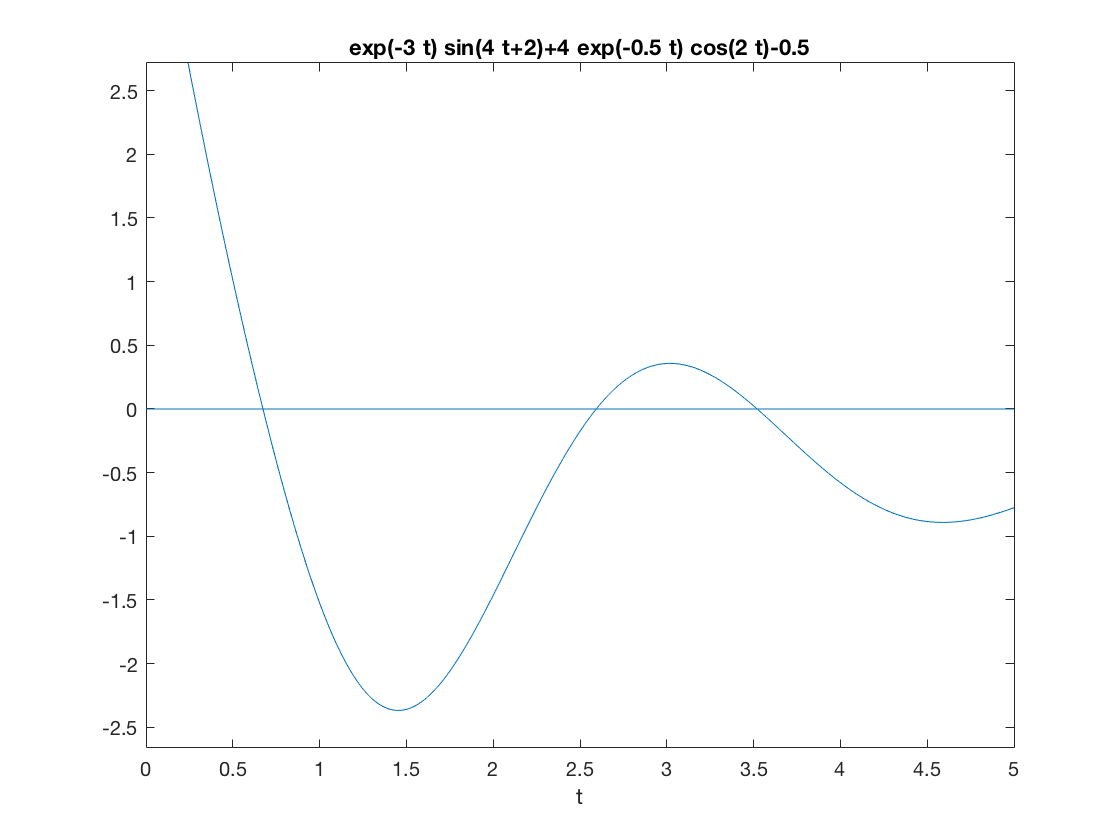

%6.1
%Equation solving using graph
ezplot('exp(-3*t)*sin(4*t+2)+4*exp(-0.5*t)*cos(2*t)-0.5',[0,5]);
line([0,5],[0,0]);

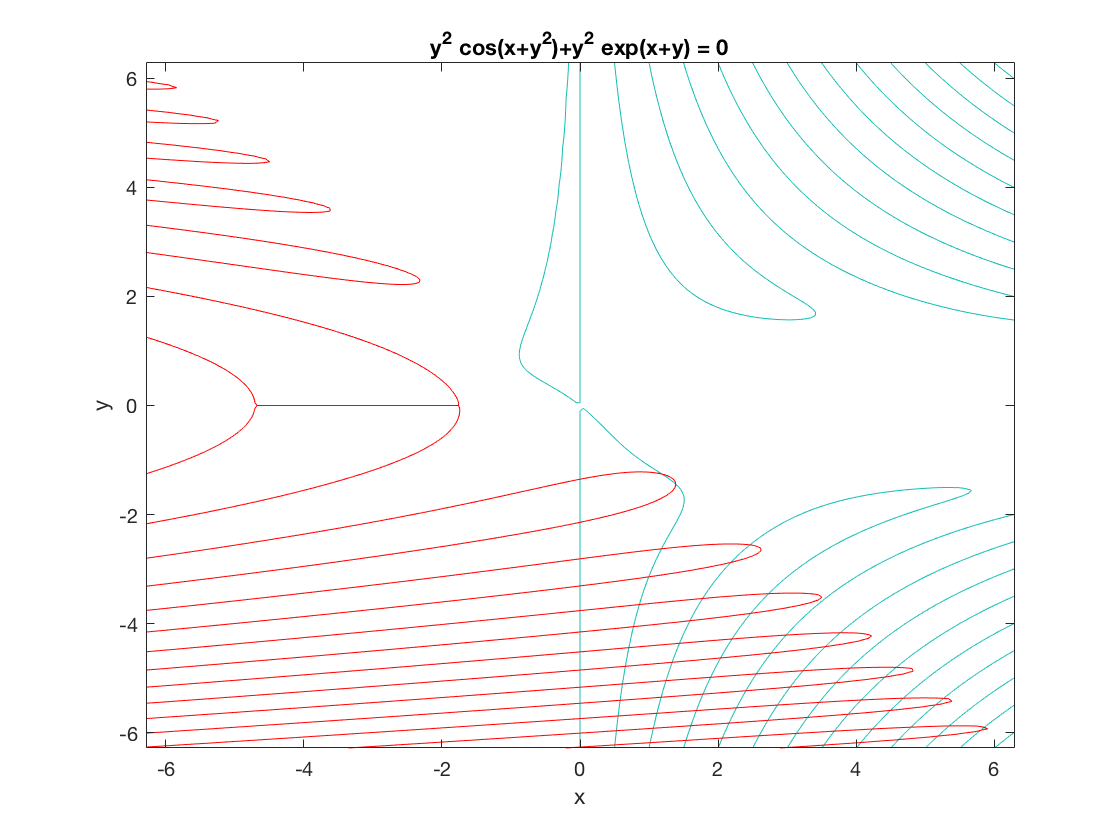

%6.2
ezplot('x^2*exp(-x*y^2/2)+exp(-x/2)*sin(x*y)');
hold on;
H=ezplot('y^2*cos(x+y^2)+y^2*exp(x+y)');
set(H,'Color','r');
hold off;

%6.3
%Equation solving using solve function
syms x y;
f1=x^2+y^2-1;
f2=75*x^3/100-y+9/10;
[sx,sy]=solve(f1,f2)

$$sy = \begin{array}{l} \left(\begin{array}{c} \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right)\\ \mathrm{root}\left(\sigma_{1},z,5\right)\\ \mathrm{root}\left(\sigma_{1},z,6\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{6}-3\,z^{4}+\frac{43\,z^{2}}{9}-\frac{16\,z}{5}+\frac{11}{25} \end{array}$$

vpa(sx,10)

$$ans = \left(\begin{array}{c} -0.9817026484\\ 0.3569699719\\ 0.8663180988-1.215371266\,\mathrm{i}\\ 0.8663180988+1.215371266\,\mathrm{i}\\ -0.5539517606-0.3547197647\,\mathrm{i}\\ -0.5539517606+0.3547197647\,\mathrm{i} \end{array}\right)$$

vpa(sy,10)

$$ans = \left(\begin{array}{c} 0.190420351\\ 0.9341158596\\ -1.491606408-0.7058820072\,\mathrm{i}\\ -1.491606408+0.7058820072\,\mathrm{i}\\ 0.9293383023-0.2114382219\,\mathrm{i}\\ 0.9293383023+0.2114382219\,\mathrm{i} \end{array}\right)$$

check=vpa(subs(f1,{x,y},{sx,sy}),10);
check=double(check');
dis=vecnorm(check,2,1);
dis=dis.*(dis>eps)

dis =      0     0     0     0     0     0


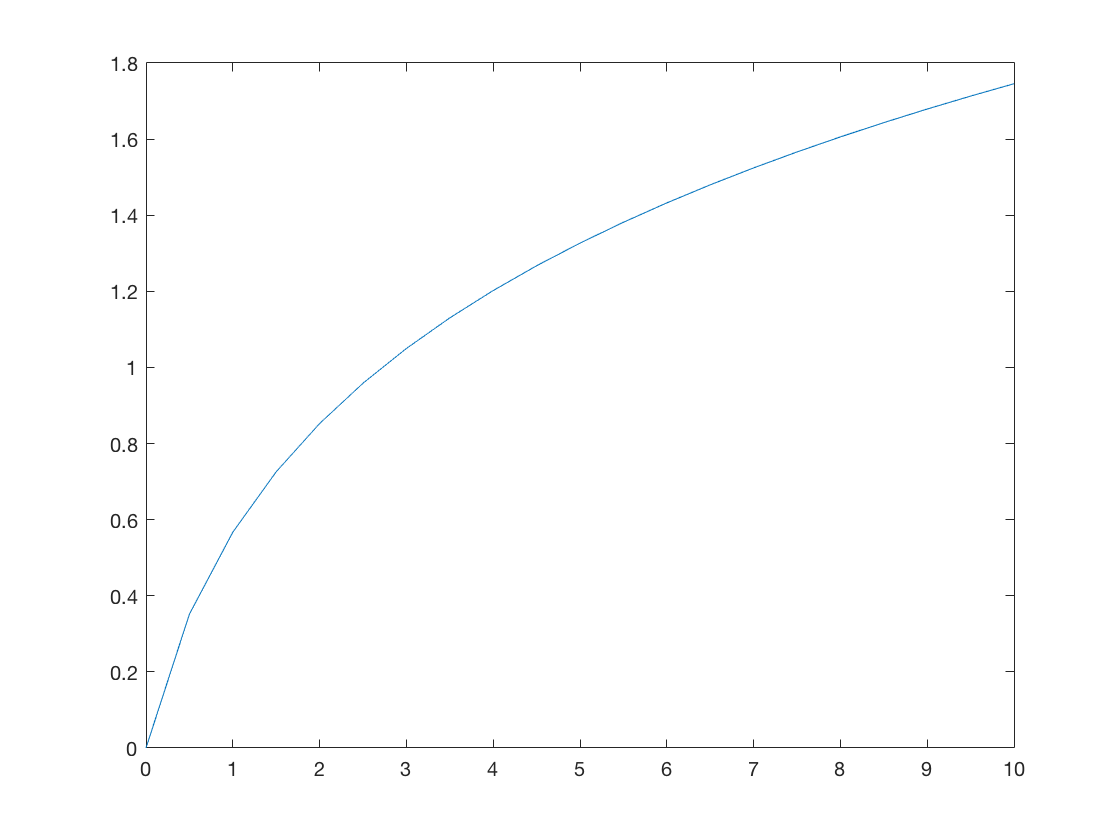

x =      1
     3
     2
     4


%6.4
x0 = 0;
xx=0:0.5:10;
yy=zeros(size(xx));
h=optimset;
h.Display='off';
for n = 1:length(xx)
    f=@(w) w*exp(w)-xx(n);
    y=fsolve(f,x0,h);
    yy(n) = y;
end
plot(xx,yy);